# Examine Well-Trained Session using Temporal Field Bayes Marginals - Ordinal Coding (Train ISC - Decode All Other InSeq)

fileDirs = [{'D:\WorkBigDataFiles\PFC\GE11_Session132'},...
    {'D:\WorkBigDataFiles\PFC\GE13_Session083'},...
    {'D:\WorkBigDataFiles\PFC\GE14_Session123'},...
    {'D:\WorkBigDataFiles\PFC\GE17_Session095'},...
    {'D:\WorkBigDataFiles\PFC\GE24_Session096'}];

binSize = 200;
dsRate = 50;
trlWindow = {[-800 2000]};
alignment = {'PokeIn'};
% trlWindow = {[-2000 800]};
% alignment = {'PokeOut'};
bayesType = 1; 
%bayseTypes: 1 = Poisson: use with raw spike counts; 2 = Bernoulli: use with binarized spike counts; 3 = Gaussian: Use with z-scored spike counts

numChancePerms = 10;

postCLim = [0 0.05];

cMap = load('roma.mat'); % flip
cMap = cMap.(cell2mat(fieldnames(cMap)));
cMap = flipud(cMap);
cMapNanW = cMap;
cMapNanW(1,:) = ones(1,3);

 %#ok<*UNRCH> 

## Compile Data

tic;
for ani = 1:length(fileDirs)
    mlb = MLB_SM(fileDirs{ani});
    % Create Analysis Variables
    if ani == 1 
        % Behavior Variables
        fiscPokeOutLat = cell(length(fileDirs),1);
        fiscRwdDelivLat = cell(length(fileDirs),1);
        % Posteriors
        realPost = cell(mlb.seqLength, 1, length(fileDirs));
        chancePost_Pos = cell(mlb.seqLength, numChancePerms, length(fileDirs));
        chancePost_Time = cell(mlb.seqLength, numChancePerms, length(fileDirs));
        chancePost_Full = cell(mlb.seqLength, numChancePerms, length(fileDirs));
    end
    mlb.binSize = binSize;
    mlb.dsRate = dsRate;
    mlb.windows = trlWindow;
    mlb.alignments = alignment;
    mlb.bayesType = bayesType;
    
    fiscPokeOutLat{ani} = ([mlb.trialInfo(mlb.fiscTrials(~isnan(mlb.fiscTrials))).PokeOutIndex] - [mlb.trialInfo(mlb.fiscTrials(~isnan(mlb.fiscTrials))).PokeInIndex])'/1000;
    fiscRwdDelivLat{ani} = ([mlb.trialInfo(mlb.fiscTrials(~isnan(mlb.fiscTrials))).RewardIndex] - [mlb.trialInfo(mlb.fiscTrials(~isnan(mlb.fiscTrials))).PokeInIndex])'/1000;
    
    % Process Observations - Train FISC, Decode ISC
    mlb.SetLikes_FISC;
    mlb.Process_Observes;
    tempPosts = mlb.OrganizeDataCellMatrix(mlb.post,3,[mlb.trialInfo(mlb.postTrlIDs).Odor],[mlb.trialInfo(mlb.postTrlIDs).Position]);
    realPost(:,1,ani) = tempPosts(logical(eye(mlb.seqLength)));
    %% Process Chance
    fprintf('.... processing chance.... ');
    for perm = 1:numChancePerms 
        mlb.Process_Observes('Full');
        tempPosts = mlb.OrganizeDataCellMatrix(mlb.post,3,[mlb.trialInfo(mlb.postTrlIDs).Odor],[mlb.trialInfo(mlb.postTrlIDs).Position]);
        chancePost_Full(:,perm,ani) = tempPosts(logical(eye(mlb.seqLength)));
        mlb.Process_Observes('Trial');
        tempPosts = mlb.OrganizeDataCellMatrix(mlb.post,3,[mlb.trialInfo(mlb.postTrlIDs).Odor],[mlb.trialInfo(mlb.postTrlIDs).Position]);
        chancePost_Pos(:,perm,ani) = tempPosts(logical(eye(mlb.seqLength)));
        mlb.Process_Observes('Time');
        tempPosts = mlb.OrganizeDataCellMatrix(mlb.post,3,[mlb.trialInfo(mlb.postTrlIDs).Odor],[mlb.trialInfo(mlb.postTrlIDs).Position]);
        chancePost_Time(:,perm,ani) = tempPosts(logical(eye(mlb.seqLength)));
    end
    fprintf('.......................... Complete\n');
end

Compiling StatMatrix Data....Completed


.... processing chance.... 

Complete


Compiling StatMatrix Data....Completed


.... processing chance.... 

Complete


Compiling StatMatrix Data....Completed


.... processing chance.... 

Complete


Compiling StatMatrix Data....Completed


.... processing chance.... 

Complete


Compiling StatMatrix Data....Completed


.... processing chance.... 

Complete


pokeOutLats = cell2mat(fiscPokeOutLat(:));
nearestPOtime = mlb.obsvTimeVect(find(mlb.obsvTimeVect<median(pokeOutLats),1,'last'));
rwdDelivLat = cell2mat(fiscRwdDelivLat(:));
nearestRWDtime = mlb.obsvTimeVect(find(mlb.obsvTimeVect<median(rwdDelivLat),1,'last'));
piNdx = find(mlb.likeTimeVect==0)+0.5;
poNdx = find(mlb.likeTimeVect==nearestPOtime)+0.5;
rwdNdx = find(mlb.likeTimeVect==nearestRWDtime)+0.5;
posNdx = find(diff(mlb.likeTimeVect)<0)+0.5;
toc

Elapsed time is 442.164072 seconds.


## Collapse Trials Across Animals

tic;
%TIP = Time-In-Position
groupPostTIP_Real = cell(mlb.seqLength,1);
groupPostTime_Real = cell(mlb.seqLength,1);
groupPostPos_Real = cell(mlb.seqLength,1);

groupPostTIP_FullChance = cell(mlb.seqLength,1);
groupPostTime_FullChance = cell(mlb.seqLength,1);
groupPostPos_FullChance = cell(mlb.seqLength,1);

groupPostTIP_PosChance = cell(mlb.seqLength,1);
groupPostTime_PosChance = cell(mlb.seqLength,1);
groupPostPos_PosChance = cell(mlb.seqLength,1);

groupPostTIP_TimeChance = cell(mlb.seqLength,1);
groupPostTime_TimeChance = cell(mlb.seqLength,1);
groupPostPos_TimeChance = cell(mlb.seqLength,1);

for pos = 1:mlb.seqLength
    % Temporal Field PDF
    groupPostTIP_Real{pos} = cell2mat(realPost(pos,:,:));
    % Marginal Time PDF
    groupPostTime_Real{pos} = mlb.TabulateBayesPost(groupPostTIP_Real{pos}, mlb.decodeIDvects(:,1));
    % Marginal Position PDF
    groupPostPos_Real{pos} = mlb.TabulateBayesPost(groupPostTIP_Real{pos}, mlb.decodeIDvects(:,3));
    % Chance - Create temporary variables to reorganize & combine chance data
    % Full Chance
    tempPostTIP_FullChance = nan(length(mlb.obsvTimeVect), length(mlb.likeTimeVect), numChancePerms);
    tempPostTime_FullChance = nan(length(mlb.obsvTimeVect), length(mlb.obsvTimeVect), numChancePerms);
    tempPostPos_FullChance = nan(length(mlb.obsvTimeVect), mlb.seqLength, numChancePerms);
    % Position Chance
    tempPostTIP_PosChance = nan(length(mlb.obsvTimeVect), length(mlb.likeTimeVect), numChancePerms);
    tempPostTime_PosChance = nan(length(mlb.obsvTimeVect), length(mlb.obsvTimeVect), numChancePerms);
    tempPostPos_PosChance = nan(length(mlb.obsvTimeVect), mlb.seqLength, numChancePerms);
    % Time Chance
    tempPostTIP_TimeChance = nan(length(mlb.obsvTimeVect), length(mlb.likeTimeVect), numChancePerms);
    tempPostTime_TimeChance = nan(length(mlb.obsvTimeVect), length(mlb.obsvTimeVect), numChancePerms);
    tempPostPos_TimeChance = nan(length(mlb.obsvTimeVect), mlb.seqLength, numChancePerms);
    parfor perm = 1:numChancePerms
        % Full Chance
        curChanceFull = cell2mat(chancePost_Full(pos,perm,:));
        tempPostTIP_FullChance(:,:,perm) = mean(curChanceFull,3);
        tempPostTime_FullChance(:,:,perm) = mean(mlb.TabulateBayesPost(curChanceFull, mlb.decodeIDvects(:,1)),3, 'omitnan'); %#ok<PFBNS> 
        tempPostPos_FullChance(:,:,perm) = mean(mlb.TabulateBayesPost(curChanceFull, mlb.decodeIDvects(:,3)),3, 'omitnan');
        % Position Chance
        curChancePos = cell2mat(chancePost_Pos(pos,perm,:));
        tempPostTIP_PosChance(:,:,perm) = mean(curChancePos,3);
        tempPostTime_PosChance(:,:,perm) = mean(mlb.TabulateBayesPost(curChancePos, mlb.decodeIDvects(:,1)),3, 'omitnan');
        tempPostPos_PosChance(:,:,perm) = mean(mlb.TabulateBayesPost(curChancePos, mlb.decodeIDvects(:,3)),3, 'omitnan');
        % Time Chance
        curChanceTime = cell2mat(chancePost_Time(pos,perm,:));
        tempPostTIP_TimeChance(:,:,perm) = mean(curChanceTime,3);
        tempPostTime_TimeChance(:,:,perm) = mean(mlb.TabulateBayesPost(curChanceTime, mlb.decodeIDvects(:,1)),3, 'omitnan');
        tempPostPos_TimeChance(:,:,perm) = mean(mlb.TabulateBayesPost(curChanceTime, mlb.decodeIDvects(:,3)),3, 'omitnan');
    end
    % Full Chance
    groupPostTIP_FullChance{pos} = mean(tempPostTIP_FullChance, 3,'omitnan');
    groupPostTime_FullChance{pos} = mean(tempPostTime_FullChance, 3, 'omitnan');
    groupPostPos_FullChance{pos} = mean(tempPostPos_FullChance, 3, 'omitnan');
    % Position Chance
    groupPostTIP_PosChance{pos} = mean(tempPostTIP_PosChance, 3,'omitnan');
    groupPostTime_PosChance{pos} = mean(tempPostTime_PosChance, 3, 'omitnan');
    groupPostPos_PosChance{pos} = mean(tempPostPos_PosChance, 3, 'omitnan');
    % Time Chance
    groupPostTIP_TimeChance{pos} = mean(tempPostTIP_TimeChance, 3,'omitnan');
    groupPostTime_TimeChance{pos} = mean(tempPostTime_TimeChance, 3, 'omitnan');
    groupPostPos_TimeChance{pos} = mean(tempPostPos_TimeChance, 3, 'omitnan');
end
numSeqs = size(groupPostTIP_Real{1},3);
toc

Elapsed time is 61.388614 seconds.


## Plot Marginals Ordinal Probabilities by Position - Full Chance

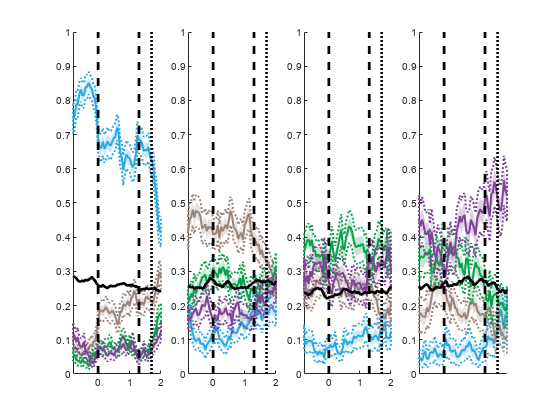

figure;
sps = nan(1,mlb.seqLength);
for obsPos = 1:mlb.seqLength
    sps(obsPos) = subplot(1,mlb.seqLength, obsPos);
    for probPos = 1:mlb.seqLength
        mlb.PlotMeanVarLine(mlb.obsvTimeVect, groupPostPos_Real{obsPos}(:,probPos,:),3,0.05,mlb.PositionColors(probPos,:));
        plot(zeros(1,2), [0 1], '--k', 'linewidth', 2);
        plot(repmat(nearestPOtime, [1,2]), [0 1], '--k', 'linewidth', 2);
        plot(repmat(nearestRWDtime, [1,2]), [0 1], ':k', 'linewidth', 2);
    end
    plot(mlb.obsvTimeVect, groupPostPos_FullChance{obsPos}(:,obsPos), '-k', 'linewidth', 2);
end
linkaxes(sps,'xy');
set(gca, 'ylim', [0 1], 'xtick', piNdx, 'xticklabel', num2cell(1:4));

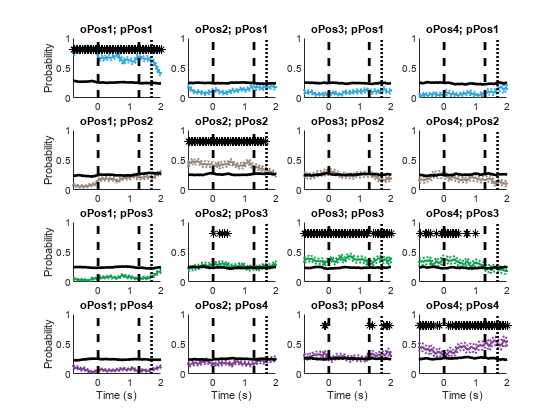

figure;
sps = nan(mlb.seqLength);
for obsPos = 1:mlb.seqLength
    for probPos = 1:mlb.seqLength
        sps(obsPos,probPos) = subplot(mlb.seqLength, mlb.seqLength, sub2ind([mlb.seqLength, mlb.seqLength], obsPos, probPos));
        mlb.PlotMeanVarLine(mlb.obsvTimeVect, groupPostPos_Real{obsPos}(:,probPos,:),3,0.05,mlb.PositionColors(probPos,:));
        plot(zeros(1,2), [0 1], '--k', 'linewidth', 2);
        plot(repmat(nearestPOtime, [1,2]), [0 1], '--k', 'linewidth', 2);
        plot(repmat(nearestRWDtime, [1,2]), [0 1], ':k', 'linewidth', 2);
        plot(mlb.obsvTimeVect, groupPostPos_FullChance{obsPos,1}(:,probPos), '-k', 'linewidth', 2);
        title(sprintf('oPos%i; pPos%i', obsPos, probPos));
        sigVect = false(1,length(mlb.obsvTimeVect));
        for t = 1:length(mlb.obsvTimeVect)
            sigVect(t) = ttest(squeeze(groupPostPos_Real{obsPos}(t,probPos,:)), groupPostPos_FullChance{obsPos,1}(t,probPos), 'Alpha', 0.05/length(mlb.obsvTimeVect), 'Tail', 'Right');
        end
        sigVect = sigVect*0.8;
        sigVect(sigVect==0) = nan;
        scatter(mlb.obsvTimeVect, sigVect, '*k');
    end
    ylabel(sps(1,obsPos), 'Probability');
    if pos==mlb.seqLength
        xlabel(gca, 'Time (s)');
    end
end
linkaxes(sps,'xy');
set(gca, 'ylim', [0 1]);

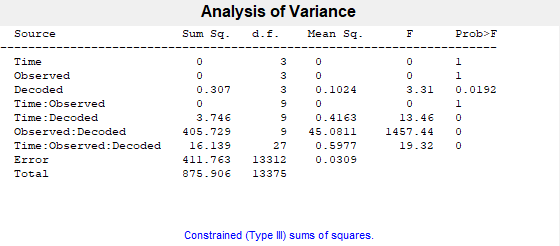

p =     1.0000
    1.0000
    0.0192
    1.0000
    0.0000
         0
    0.0000


tbl = 10×7 cell array
    {'Source'               }    {'Sum Sq.' }    {'d.f.' }    {'Singular?'}    {'Mean Sq.'}    {'F'         }    {'Prob>F'    }
    {'Time'                 }    {[       0]}    {[    3]}    {[        0]}    {[       0]}    {[         0]}    {[         1]}
    {'Observed'             }    {[       0]}    {[    3]}    {[        0]}    {[       0]}    {[         0]}    {[         1]}
    {'Decoded'              }    {[  0.3072]}    {[    3]}    {[        0]}    {[  0.1024]}    {[    3.3109]}    {[    0.0192]}
    {'Time:Observed'        }    {[       0]}    {[    9]}    {[        0]}    {[       0]}    {[         0]}    {[         1]}
    {'Time:Decoded'         }    {[  3.7464]}    {[    9]}    {[        0]}    {[  0.4163]}    {[   13.4577]}    {[1.0054e-21]}
    {'Observed:Decoded'     }    {[405.7295]}    {[    9]}    {[        0]}    {[ 45.0811]}    {[1.4574e+03]}    {[         0]}
    {'Time:Observed:Decoded'}    {[ 16.1386]}    {[   27]}    {[        0]}    {[ 

stats = struct with fields:
         source: 'anovan'
          resid: [13376×1 double]
         coeffs: [125×1 double]
            Rtr: [64×64 double]
       rowbasis: [64×125 double]
            dfe: 13312
            mse: 0.0309
    nullproject: [125×64 double]
          terms: [7×3 double]
        nlevels: [3×1 double]
     continuous: [0 0 0]
         vmeans: [3×1 double]
       termcols: [8×1 double]
     coeffnames: {125×1 cell}
           vars: [125×3 double]
       varnames: {3×1 cell}
       grpnames: {3×1 cell}
        vnested: []
            ems: [8×8 double]
          denom: []
        dfdenom: []
        msdenom: []
         varest: []
          varci: []
       txtdenom: []
         txtems: []
        rtnames: []


preTrialLog = mlb.obsvTimeVect>=-0.5 & mlb.obsvTimeVect<0;
rlyTrialLog = mlb.obsvTimeVect>=0 & mlb.obsvTimeVect<0.5;
latTrialLog = mlb.obsvTimeVect>nearestPOtime-0.5 & mlb.obsvTimeVect<=nearestPOtime;
pstTrialLog = mlb.obsvTimeVect>nearestPOtime & mlb.obsvTimeVect<=nearestPOtime+0.5;

anovaDta = cell(mlb.seqLength, mlb.seqLength);
obsPosID = cell(mlb.seqLength, mlb.seqLength);
decPosID = cell(mlb.seqLength, mlb.seqLength);
timeEpochID = cell(mlb.seqLength, mlb.seqLength);
odLagID = cell(mlb.seqLength, mlb.seqLength);
for obsPos = 1:mlb.seqLength
    tempObs = groupPostPos_Real{obsPos};
    for decPos = 1:mlb.seqLength
        tempData = [mean(tempObs(preTrialLog,decPos,:),1, 'omitnan');...
            mean(tempObs(rlyTrialLog,decPos,:),1, 'omitnan');...
            mean(tempObs(latTrialLog,decPos,:),1, 'omitnan');...
            mean(tempObs(pstTrialLog,decPos,:),1, 'omitnan')];
        anovaDta{obsPos,decPos} = squeeze(tempData);
        obsPosID{obsPos,decPos} = zeros(size(anovaDta{obsPos,decPos}))+obsPos;
        decPosID{obsPos,decPos} = zeros(size(anovaDta{obsPos,decPos}))+decPos;
        odLagID{obsPos,decPos} = zeros(size(anovaDta{obsPos,decPos}))+(decPos-obsPos);
        timeEpochID{obsPos,decPos} = squeeze(repmat((1:4)', [1,1,size(tempData,3)]));
    end
end
anovaDta = squeeze(cell2mat(anovaDta(:)'));
obsPosID = squeeze(cell2mat(obsPosID(:)'));
decPosID = squeeze(cell2mat(decPosID(:)'));
timeEpochID = squeeze(cell2mat(timeEpochID(:)'));
figure;
[p,tbl,stats] = anovan(anovaDta(:), {timeEpochID(:), obsPosID(:), decPosID(:)},...
    'model', 'full', 'varnames', {'Time', 'Observed', 'Decoded'}, 'SSType', 3)

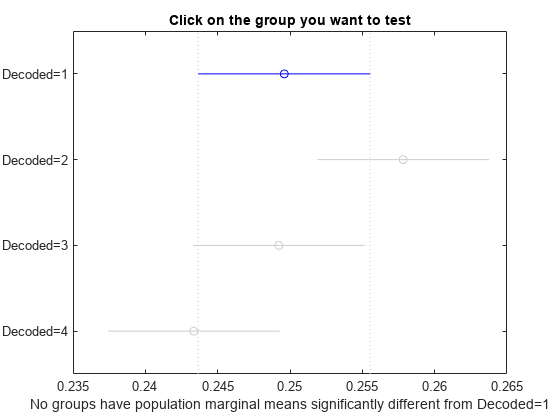

figure; multcompare(stats, 'Dimension', 3);

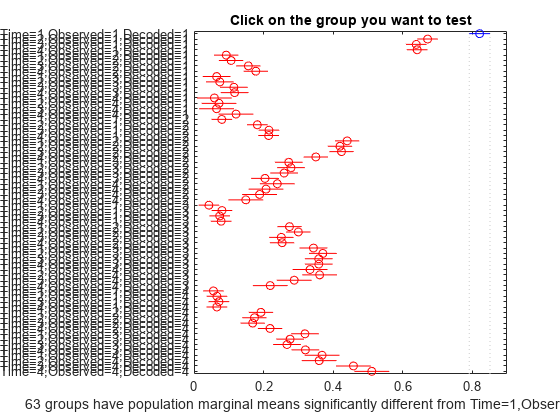

figure; multcompare(stats, 'Dimension', [1 2 3], 'CriticalValueType','bonferroni');

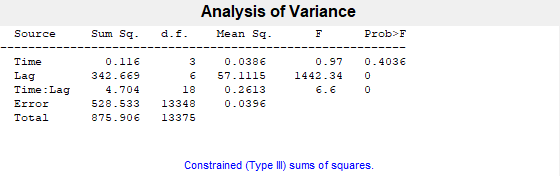

p =     0.4036
         0
    0.0000


tbl = 6×7 cell array
    {'Source'  }    {'Sum Sq.' }    {'d.f.' }    {'Singular?'}    {'Mean Sq.'}    {'F'         }    {'Prob>F'    }
    {'Time'    }    {[  0.1158]}    {[    3]}    {[        0]}    {[  0.0386]}    {[    0.9746]}    {[    0.4036]}
    {'Lag'     }    {[342.6693]}    {[    6]}    {[        0]}    {[ 57.1115]}    {[1.4423e+03]}    {[         0]}
    {'Time:Lag'}    {[  4.7037]}    {[   18]}    {[        0]}    {[  0.2613]}    {[    6.5995]}    {[8.6429e-17]}
    {'Error'   }    {[528.5329]}    {[13348]}    {[        0]}    {[  0.0396]}    {0×0 double  }    {0×0 double  }
    {'Total'   }    {[875.9059]}    {[13375]}    {[        0]}    {0×0 double}    {0×0 double  }    {0×0 double  }


stats = struct with fields:
         source: 'anovan'
          resid: [13376×1 double]
         coeffs: [40×1 double]
            Rtr: [28×28 double]
       rowbasis: [28×40 double]
            dfe: 13348
            mse: 0.0396
    nullproject: [40×28 double]
          terms: [3×2 double]
        nlevels: [2×1 double]
     continuous: [0 0]
         vmeans: [2×1 double]
       termcols: [4×1 double]
     coeffnames: {40×1 cell}
           vars: [40×2 double]
       varnames: {2×1 cell}
       grpnames: {2×1 cell}
        vnested: []
            ems: [4×4 double]
          denom: []
        dfdenom: []
        msdenom: []
         varest: []
          varci: []
       txtdenom: []
         txtems: []
        rtnames: []



odLagID = squeeze(cell2mat(odLagID(:)'));
figure;
[p,tbl,stats] = anovan(anovaDta(:), {timeEpochID(:), odLagID(:)},...
    'model', 'full', 'varnames', {'Time', 'Lag'}, 'SSType', 3)

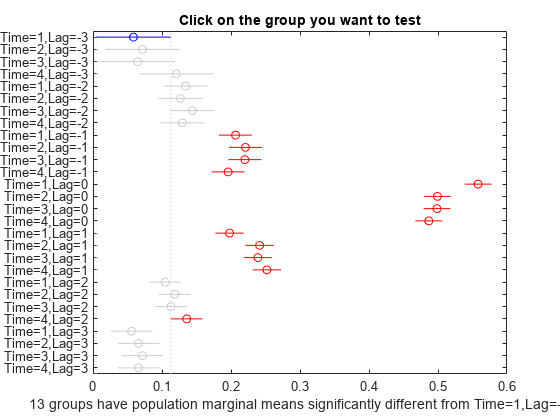

figure; multcompare(stats, 'Dimension', [1 2], 'CriticalValueType','bonferroni');

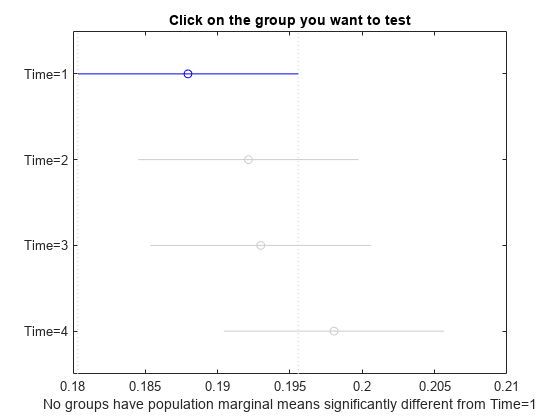

figure; multcompare(stats, 'Dimension', 1);

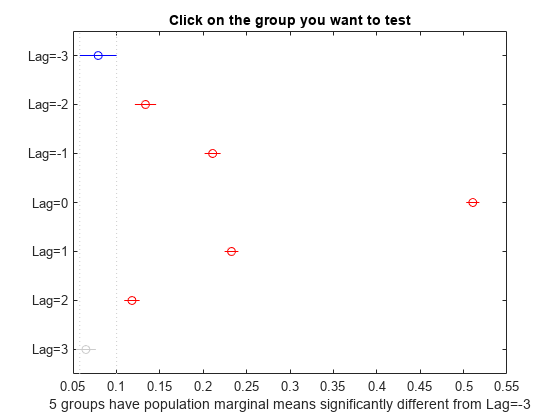

ans =     1.0000    2.0000   -0.0871   -0.0545   -0.0219    0.0000
    1.0000    3.0000   -0.1623   -0.1318   -0.1014         0
    1.0000    4.0000   -0.4610   -0.4316   -0.4022         0
    1.0000    5.0000   -0.1833   -0.1536   -0.1239         0
    1.0000    6.0000   -0.0692   -0.0389   -0.0086    0.0029
    1.0000    7.0000   -0.0178    0.0142    0.0463    0.8490
    2.0000    3.0000   -0.0990   -0.0774   -0.0557         0
    2.0000    4.0000   -0.3972   -0.3771   -0.3570         0
    2.0000    5.0000   -0.1196   -0.0991   -0.0786         0
    2.0000    6.0000   -0.0058    0.0156    0.0370    0.3226


figure; multcompare(stats, 'Dimension', 2)

## Plot Marginal Ordinal Probabilities - Time Chance

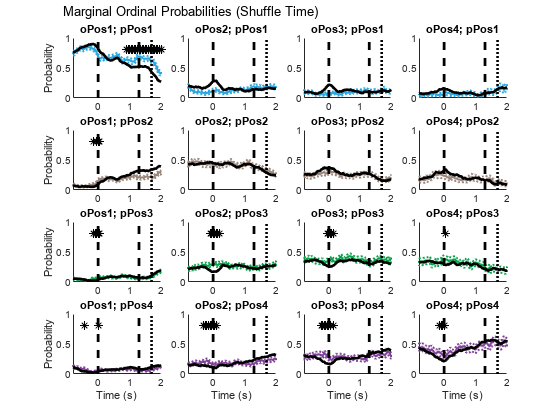

figure;
sps = nan(mlb.seqLength);
for obsPos = 1:mlb.seqLength
    for probPos = 1:mlb.seqLength
        sps(obsPos,probPos) = subplot(mlb.seqLength, mlb.seqLength, sub2ind([mlb.seqLength, mlb.seqLength], obsPos, probPos));
        mlb.PlotMeanVarLine(mlb.obsvTimeVect, groupPostPos_Real{obsPos}(:,probPos,:),3,0.05,mlb.PositionColors(probPos,:));
        plot(zeros(1,2), [0 1], '--k', 'linewidth', 2);
        plot(repmat(nearestPOtime, [1,2]), [0 1], '--k', 'linewidth', 2);
        plot(repmat(nearestRWDtime, [1,2]), [0 1], ':k', 'linewidth', 2);
        plot(mlb.obsvTimeVect, groupPostPos_TimeChance{obsPos,1}(:,probPos), '-k', 'linewidth', 2);
        title(sprintf('oPos%i; pPos%i', obsPos, probPos));
        sigVect = false(1,length(mlb.obsvTimeVect));
        for t = 1:length(mlb.obsvTimeVect)
            sigVect(t) = ttest(squeeze(groupPostPos_Real{obsPos}(t,probPos,:)), groupPostPos_TimeChance{obsPos,1}(t,probPos), 'Alpha', 0.05/length(mlb.obsvTimeVect), 'Tail', 'Right');
        end
        sigVect = sigVect*0.8;
        sigVect(sigVect==0) = nan;
        scatter(mlb.obsvTimeVect, sigVect, '*k');
    end
    ylabel(sps(1,obsPos), 'Probability');
    if pos==mlb.seqLength
        xlabel(gca, 'Time (s)');
    end
end
linkaxes(sps,'xy');
set(gca, 'ylim', [0 1]);
annotation(gcf,'textbox', [0.1 0.95 0.9 0.05],...
        'String', 'Marginal Ordinal Probabilities (Shuffle Time)',...
        'FontSize',10, 'edgecolor', 'none', 'horizontalalignment', 'left');

## Plot Marginal Ordinal Probabilities - Position Chance

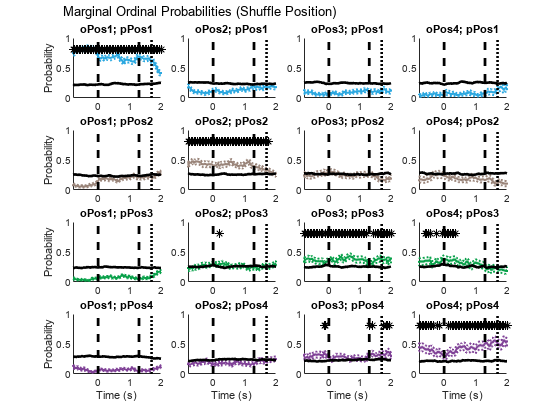

figure;
sps = nan(mlb.seqLength);
for obsPos = 1:mlb.seqLength
    for probPos = 1:mlb.seqLength
        sps(obsPos,probPos) = subplot(mlb.seqLength, mlb.seqLength, sub2ind([mlb.seqLength, mlb.seqLength], obsPos, probPos));
        mlb.PlotMeanVarLine(mlb.obsvTimeVect, groupPostPos_Real{obsPos}(:,probPos,:),3,0.05,mlb.PositionColors(probPos,:));
        plot(zeros(1,2), [0 1], '--k', 'linewidth', 2);
        plot(repmat(nearestPOtime, [1,2]), [0 1], '--k', 'linewidth', 2);
        plot(repmat(nearestRWDtime, [1,2]), [0 1], ':k', 'linewidth', 2);
        plot(mlb.obsvTimeVect, groupPostPos_PosChance{obsPos,1}(:,probPos), '-k', 'linewidth', 2);
        title(sprintf('oPos%i; pPos%i', obsPos, probPos));
        sigVect = false(1,length(mlb.obsvTimeVect));
        for t = 1:length(mlb.obsvTimeVect)
            sigVect(t) = ttest(squeeze(groupPostPos_Real{obsPos}(t,probPos,:)), groupPostPos_PosChance{obsPos,1}(t,probPos), 'Alpha', 0.05/length(mlb.obsvTimeVect), 'Tail', 'Right');
        end
        sigVect = sigVect*0.8;
        sigVect(sigVect==0) = nan;
        scatter(mlb.obsvTimeVect, sigVect, '*k');
    end
    ylabel(sps(1,obsPos), 'Probability');
    if pos==mlb.seqLength
        xlabel(gca, 'Time (s)');
    end
end
linkaxes(sps,'xy');
set(gca, 'ylim', [0 1]);
annotation(gcf,'textbox', [0.1 0.95 0.9 0.05],...
        'String', 'Marginal Ordinal Probabilities (Shuffle Position)',...
        'FontSize',10, 'edgecolor', 'none', 'horizontalalignment', 'left');